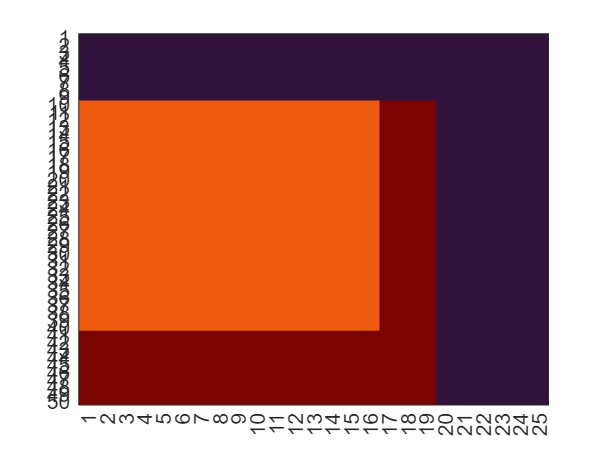

%mesh
N_x=25;
N_y=50;
z=4;
%define
t=zeros(N_x*N_y,1);
t_neo=zeros(N_x*N_y,1);
b=zeros(N_x*N_y,1);
A=zeros(N_x*N_y,N_x*N_y);
t_para=zeros(N_y,N_x);
temp=zeros(N_y,N_x);
temp_neo=zeros(N_y,N_x);

%inital condition
material=zeros(N_y,N_x);

%al
material(:,:)=0.4;
 temp_neo(9:N_y-9,1:16)=600;
% temp_neo(10:15,10:15)=600;
%cup
material(:,N_x-8:N_x-5)=0.5;
material(N_y-9:N_y,:)=0.5;
temp_neo(:,N_x-8:N_x-5)=500;
temp_neo(N_y-9:N_y,:)=500;
%air
material(1:9,:)=0.001;
material(:,N_x-5:N_x)=0.001;
temp_neo(1:9,:)=200;
temp_neo(:,N_x-5:N_x)=200;

heatmap(material,'ColorbarVisible','off','GridVisible','off','Colormap',turbo);

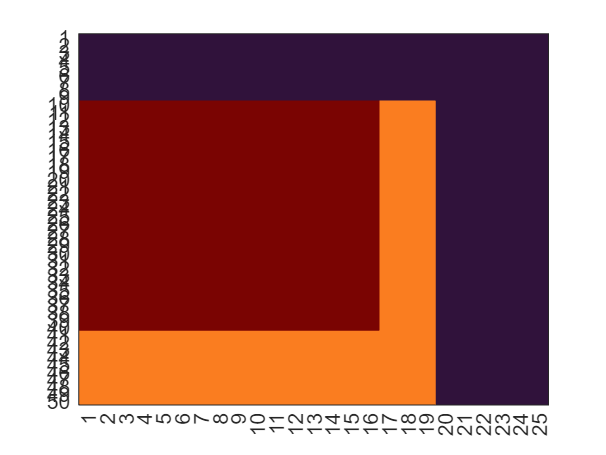

t=temp_neo(:);
heatmap(temp_neo,'ColorbarVisible','off','GridVisible','off','Colormap',turbo);

fo=1;


for time=1:50

    for y=1:1:N_y
        for x=1:1:N_x

            t_para(y,x)=1+z*material(y,x);
            if y>1
                t_para(y-1,x)=-min(material(y,x),material(y-1,x));
                else
                t_para(y,x)=t_para(y,x)-material(y,x);
            end
            if y<N_y
                t_para(y+1,x)=-min(material(y,x),material(y+1,x));
                else
                t_para(y,x)=t_para(y,x)-material(y,x);
            end
            if x>1
                t_para(y,x-1)=-min(material(y,x),material(y,x-1));
            else
                t_para(y,x)=t_para(y,x)-material(y,x);
            end
            if x<N_x
                t_para(y,x+1)=-min(material(y,x),material(y,x+1));
                else
                t_para(y,x)=t_para(y,x)-material(y,x);
            end
            A((y-1)*N_x+x,:)=t_para(:);
            b((y-1)*N_x+x,1)=temp_neo(y,x)+0.1;
         
            t_para=zeros(N_y,N_x);
        end

    end

    t_neo=A\b;
    temp_neo=reshape(t_neo,N_y,N_x);

    h= heatmap(temp_neo,'Colormap',turbo,'ColorLimits',[0 600]);

%     temp_neo(1,:)=temp_neo(2,:);
%     temp_neo(:,1)=temp_neo(:,2);
%     temp_neo(N_y,:)=temp_neo(N_y-1,:);
%     temp_neo(:,N_x)=temp_neo(:,N_x-1);
%     %     temp=temp_neo;
%      temp_neo=temp_neo';
    pause(0.1)
    t=temp_neo(:);

         A=zeros(N_x*N_y,N_x*N_y);
end

位置 1 处的索引无效。数组索引必须为正整数或逻辑值。